%% Preparación del entorno
clear;
clc;
close all;

%% Definición simbólica del sistema
syms p53 Stat3 Np63 PNp63
assume(PNp63 >= 0)

% Parámetros
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
Pstat3 = 0.9819;
%PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

bifurcacion = []; % Para almacenar [PNp63, p53, Stat3, Np63, estabilidad]

% Variables simbólicas a resolver
vars = [p53, Stat3, Np63];

% Preparar vector de valores para PNp63
PNp63_vals = linspace(0, 100, 200);
resultados = [];

for i = 1:length(PNp63_vals)
    valor_P = PNp63_vals(i);

    % Resolver el sistema con estos valores
    ecuaciones = [subs(f1, PNp63, valor_P) == 0, ...
                  subs(f2, PNp63, valor_P) == 0, ...
                  subs(f3, PNp63, valor_P) == 0];

    % Semillas iniciales para intentar múltiples soluciones
    seeds = [
        0.1 0.1 0.1;
        1   1   1;
        5   5   5;
        10  10  10;
        20  20  20;
        30  30  30;
        40  40  40;
        50  50  50;
    ];

    sols_unicos = [];

    % Intentar resolver desde diferentes semillas
    for s = 1:size(seeds, 1)
        seed = seeds(s, :);

        try
            soluciones = vpasolve(ecuaciones, vars, seed);
            x1 = double(soluciones.p53);
            x2 = double(soluciones.Stat3);
            x3 = double(soluciones.Np63);

            if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
                nueva_sol = [x1 x2 x3];

                % Eliminar soluciones duplicadas por tolerancia
                if isempty(sols_unicos) || all(vecnorm(sols_unicos - nueva_sol, 2, 2) > 1e-3)
                    sols_unicos = [sols_unicos; nueva_sol];
                end
            end
        catch
            continue
        end
    end

    
    % Convertir soluciones a vectores numéricos (puede haber varias)
    p53_sol = double(soluciones.p53);
    Stat3_sol = double(soluciones.Stat3);
    Np63_sol = double(soluciones.Np63);
    
    for j = 1:length(p53_sol)
        x1 = p53_sol(j);
        x2 = Stat3_sol(j);
        x3 = Np63_sol(j);

        % Verificar si el punto es real y no negativo
        if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
            % Construir la matriz Jacobiana en el punto
            J = jacobian([f1, f2, f3], [p53, Stat3, Np63]);
            J_num = double(subs(J, [p53, Stat3, Np63, PNp63], [x1, x2, x3, valor_P]));
            autovalores = eig(J_num);
            
            % Clasificación básica de estabilidad
            if all(real(autovalores) < 0)
                tipo = "Estable";
            elseif any(real(autovalores) > 0) && any(real(autovalores) < 0)
                tipo = "Silla";
            else
                tipo = "Inestable";
            end
            
            % Guardar resultado
            resultados = [resultados; {valor_P, x1, x2, x3, tipo}];
        end
    end
end

% Convertir resultados a tabla
bifurcacion_tbl = cell2table(resultados, 'VariableNames', ...
    {'PNp63', 'p53', 'Stat3', 'Np63', 'Estabilidad'});

% Mostrar una parte de la tabla
disp(head(bifurcacion_tbl, 10))

     PNp63      p53      Stat3      Np63     Estabilidad
    _______    ______    ______    ______    ___________

          0    7.9061    10.992    5.1893     "Estable" 
    0.50251    7.8845    10.966    5.3462     "Estable" 
      1.005    7.8643    10.942    5.5006     "Estable" 
     1.5075    7.8454    10.919    5.6524     "Estable" 
     2.0101    7.8277    10.898    5.8017     "Estable" 
     2.5126     7.811    10.878    5.9488     "Estable" 
     3.0151    7.7953    10.859    6.0936     "Estable" 
     3.5176    7.7804    10.841    6.2363     "Estable" 
     4.0201    7.7663    10.825     6.377     "Estable" 
     4.5226     7.753    10.809    6.5156     "Estable" 



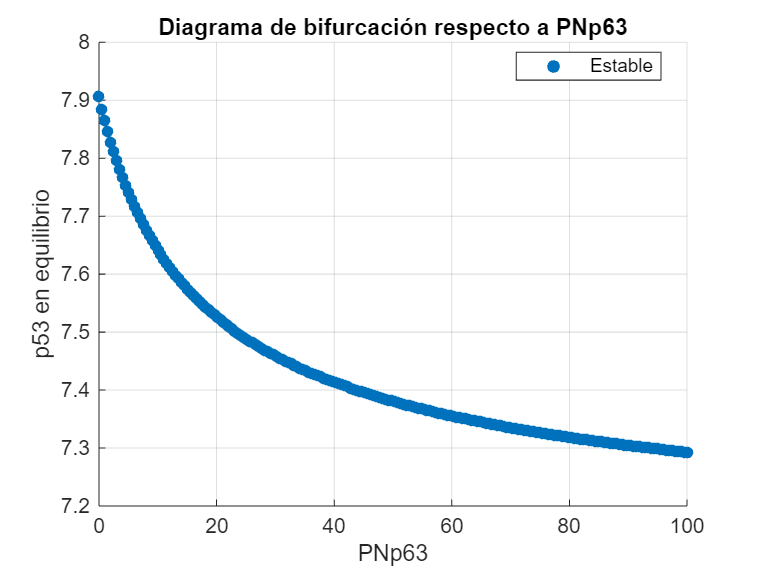


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.PNp63(idx), bifurcacion_tbl.p53(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('PNp63'); ylabel('p53 en equilibrio');
title('Diagrama de bifurcación respecto a PNp63');
legend('Location', 'best');
grid on;

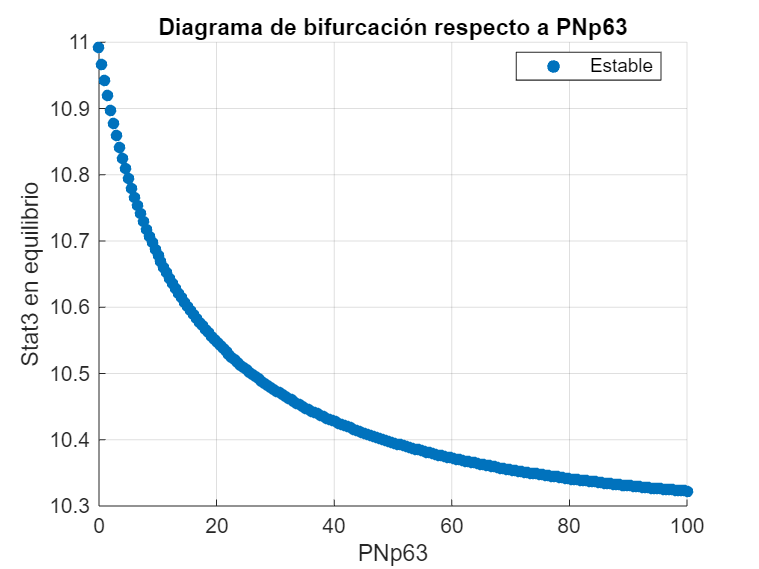



% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.PNp63(idx), bifurcacion_tbl.Stat3(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('PNp63'); ylabel('Stat3 en equilibrio');
title('Diagrama de bifurcación respecto a PNp63');
legend('Location', 'best');
grid on;

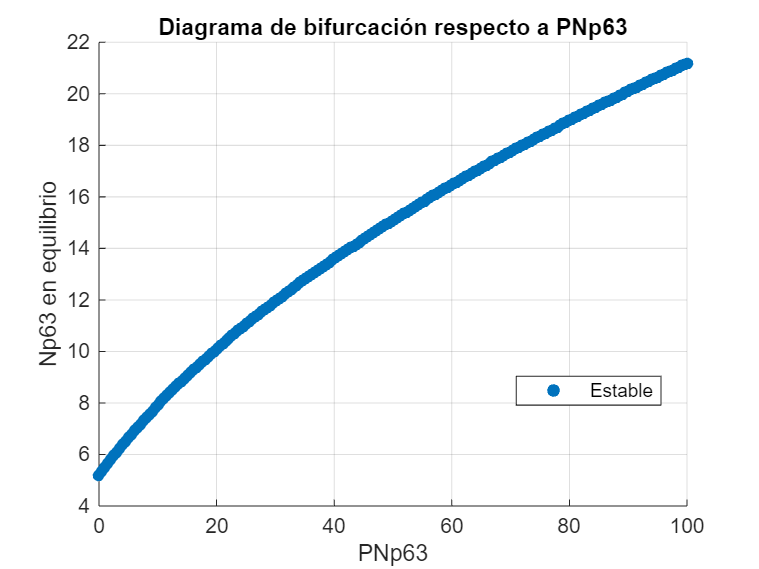


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.PNp63(idx), bifurcacion_tbl.Np63(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('PNp63'); ylabel('Np63 en equilibrio');
title('Diagrama de bifurcación respecto a PNp63');
legend('Location', 'best');
grid on;

resultados

resultados = 200×5 cell array
    {[     0]}    {[7.9061]}    {[10.9918]}    {[5.1893]}    {["Estable"]}
    {[0.5025]}    {[7.8845]}    {[10.9659]}    {[5.3462]}    {["Estable"]}
    {[1.0050]}    {[7.8643]}    {[10.9417]}    {[5.5006]}    {["Estable"]}
    {[1.5075]}    {[7.8454]}    {[10.9190]}    {[5.6524]}    {["Estable"]}
    {[2.0101]}    {[7.8277]}    {[10.8978]}    {[5.8017]}    {["Estable"]}
    {[2.5126]}    {[7.8110]}    {[10.8778]}    {[5.9488]}    {["Estable"]}
    {[3.0151]}    {[7.7953]}    {[10.8591]}    {[6.0936]}    {["Estable"]}
    {[3.5176]}    {[7.7804]}    {[10.8414]}    {[6.2363]}    {["Estable"]}
    {[4.0201]}    {[7.7663]}    {[10.8247]}    {[6.3770]}    {["Estable"]}
    {[4.5226]}    {[7.7530]}    {[10.8089]}    {[6.5156]}    {["Estable"]}
    {[5.0251]}    {[7.7403]}    {[10.7939]}    {[6.6523]}    {["Estable"]}
    {[5.5276]}    {[7.7282]}    {[10.7796]}    {[6.7872]}    {["Estable"]}
    {[6.0302]}    {[7.7167]}    {[10.7661]}    {[6.9203]}    {["Establ